data = readtable('logs/wins.csv');
data = table2array(data(:,1:4));
player_0 = data(:,1);
player_1= data(:,2);
player_2= data(:,3);
player_3= data(:,4);
max(player_0)

ans = 67

min(player_0)

ans = 35

data_mean = mean(data)

data_mean =    51.8850   16.4080   15.8680   15.8390


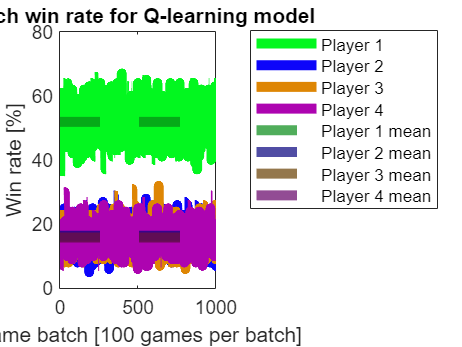

green = [2, 247, 31]/255;
green_mean = [6, 138, 21]/255;
blue = [13, 5, 250]/255;
blue_mean = [6, 2, 125]/255;
orange = [222, 134, 4]/255;
orange_mean = [102, 61, 0]/255;
purple = [173, 4, 176]/255;
purple_mean = [100, 0, 102]/255;

figure(1)
plot([1:length(data(:,1))],player_0,"color", green,"LineWidth",5)
hold on
plot([1:length(data(:,1))],player_1,"color", blue,"LineWidth",5)
plot([1:length(data(:,1))],player_2,"color", orange, "LineWidth",5)
plot([1:length(data(:,1))],player_3,"color", purple, "LineWidth",5)

yline(data_mean(1),'--',"Color",green_mean, "LineWidth",5)
yline(data_mean(2),'--',"Color",blue_mean,"LineWidth",5)
yline(data_mean(3),'--',"Color",orange_mean,"LineWidth",5)
yline(data_mean(4),'--',"Color",purple_mean,"LineWidth",5)

legend("Player 1","Player 2","Player 3", "Player 4", ...
    "Player 1 mean","Player 2 mean","Player 3 mean", "Player 4 mean",'NumColumns',1, "location","bestoutside")
xlabel("Game batch [100 games per batch]")
ylabel("Win rate [%]")
title("Batch win rate for Q-learning model")
hold off

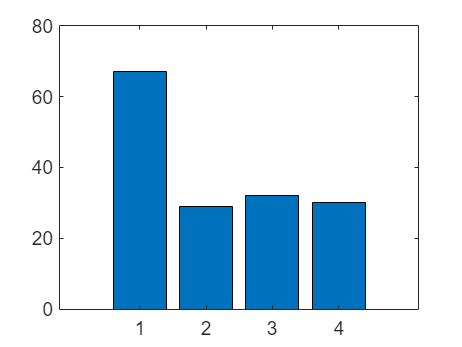


max_wins = [max(player_0),max(player_1), max(player_2), max(player_3)];
bar(max_wins)

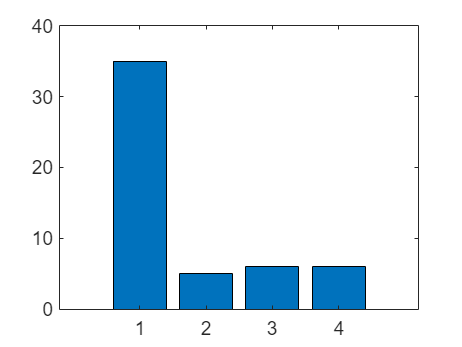



min_wins = [min(player_0),min(player_1), min(player_2), min(player_3)];
bar(min_wins)

## Sanity check

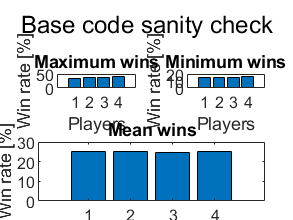

data = readtable('logs/sanity_check.csv');
data = table2array(data(:,1:4));
player_0 = data(:,1);
player_1= data(:,2);
player_2= data(:,3);
player_3= data(:,4);
max(player_0);
min(player_0);
data_mean = mean(data);

figure(2)
sgtitle("Base code sanity check")
max_wins = [max(player_0),max(player_1), max(player_2), max(player_3)];
subplot(2,2,1)
bar(max_wins)
ylim([0,50])
title("Maximum wins")
xlabel("Players")
ylabel("Win rate [%]")

min_wins = [min(player_0),min(player_1), min(player_2), min(player_3)];
subplot(2,2,2)
bar(min_wins)
title("Minimum wins")
xlabel("Players")
ylabel("Win rate [%]")


mean_wins = [mean(player_0),mean(player_1), mean(player_2), mean(player_3)];
subplot(2,2,[3,4])
bar(mean_wins)
ylim([0,30])
title("Mean wins")
xlabel("Players")
ylabel("Win rate [%]")